clc; close all; clearvars;

## Parameters for generate the data set

d=3; %dimensionality
c=3; % quantity classes

m1=[-0.5622721686261278 1.1704601236336887 -0.6081879550075613]'; %means vectors
m2=[0.6904692449166845 0.08872418498635462 -0.7791934299030396]';
m3=[0.19756948018729084 -0.36619207554951666 0.1686225953622233]';
m=[m1 m2 m3];
% 
S1=[0.035372  0.001631  0.061266; 0.001631  0.382650 -0.058443; 0.061266 -0.058443  0.509344]; %covariance matrices 
S2=[0.107327  0.059705  0.190813; 0.059705  0.171434 -0.002145; 0.190813 -0.002145  1.046333];
S3=[0.800716 -0.529648  0.404252; -0.529648  1.363328 -0.658907; 0.404252 -0.658907  1.260925];
S(:,:,1)=S1;S(:,:,2)=S2;S(:,:,3)=S3;

% A priori probabilities
P1=1/3;  P2=1/3; P3=1/3 ;
P=[P1 P2 P3]';


**Quantities of data for each class**

N=300;

N1=fix(N*P1); N2=fix(N*P2); N3=fix( N*P3);

Nt=150;

N1t=fix(Nt*P1); N2t=fix(Nt*P2); N3t=fix( Nt*P3);

## Generate data set training: Xtrain (entrenamiento)

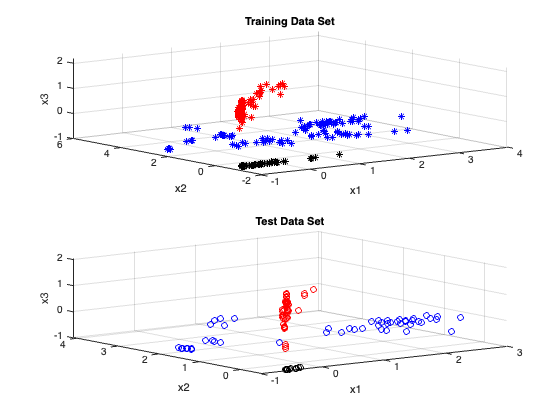

% randn('seed',0);
% [Xtrain,ytrain]=generate_gauss_classes(m,S,P,N);
Xtrain = csvread('../Dataset/Train_InputT3.csv');
ytrain = csvread('../Dataset/Train_TargetsT3.csv');

% Generate Xtest (prueba)
% randn('seed',100);
% [Xtest,ytest]=generate_gauss_classes(m,S,P,N);
Xtest = csvread('../Dataset/Test_InputT3.csv');
ytest = csvread('../Dataset/Test_TargetsT3.csv');
% Display Xtrain (Entrenamiento.....) 
subplot(2,1,1); plot3(Xtrain(1,1:N1),Xtrain(2,1:N1),Xtrain(3,1:N1),'*r',Xtrain(1,N1+1:N1+N2),...
    Xtrain(2,N1+1:N1+N2),Xtrain(3,N1+1:N1+N2),'*b', Xtrain(1,N1+N2+1:N1+N2+N3),...
    Xtrain(2,N1+N2+1:N1+N2+N3),Xtrain(3,N1+N2+1:N1+N2+N3),'*k'); 
grid on; title('Training Data Set'); xlabel('x1');ylabel('x2');zlabel('x3');

% Display Xtest (Prueba)
subplot(2,1,2); plot3(Xtest(1,1:N1t),Xtest(2,1:N1t),Xtest(3,1:N1t),'or',Xtest(1,N1t+1:N1t+N2t),...
    Xtest(2,N1t+1:N1t+N2t),Xtest(3,N1t+1:N1t+N2t),'ob', Xtest(1,N1t+N2t+1:N1t+N2t+N3t),...
    Xtest(2,N1t+N2t+1:N1t+N2t+N3t),Xtest(3,N1t+N2t+1:N1t+N2t+N3t),'ok'); 
grid on; title('Test Data Set'); xlabel('x1');ylabel('x2');zlabel('x3');

## 1. Compute the ML estimated of the mean values and covariance matrix using function Gaussian

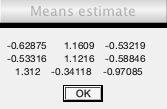

class1_data=Xtrain(:,find(ytrain==1));
[m1_est, S1_est]=Gaussian_ML_estimate(class1_data);

class2_data=Xtrain(:,find(ytrain==2));
[m2_est, S2_est]=Gaussian_ML_estimate(class2_data);

class3_data=Xtrain(:,find(ytrain==3));
[m3_est, S3_est]=Gaussian_ML_estimate(class3_data);

%S_est=(1/3)*(S1_est+S2_est+S3_est); %% promedio
S_est(:,:,1)=S1_est;S_est(:,:,2)=S2_est;S_est(:,:,3)=S3_est; %Matriz de matrices

m_est=[m1_est m2_est m3_est];


%Display means vectors and Covariance Matrices ORIGINALS
options.WindowStyle = 'normal';

% h1=msgbox(num2str(m),'Orig Means');

% h2=msgbox(num2str(S1),'Orig S1');
% h3=msgbox(num2str(S2),'Orig S2');
% h4=msgbox(num2str(S3), 'Orig S3');


%Display means vectors and Covariance Matrices Estimates
msgbox(num2str(m_est),'Means estimate');

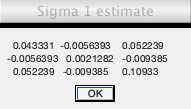

msgbox(num2str(S1_est),'Sigma 1 estimate');

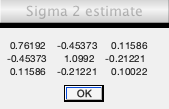

msgbox(num2str(S2_est),'Sigma 2 estimate');

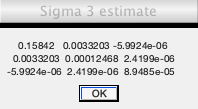

msgbox(num2str(S3_est), 'Sigma 3 estimate');

## 2. Euclidean distance classifier, using the ML estimated of the means, in order to **classify the data vectors of Xp**

z_euclidean=euclidean_classifier(m_est,Xtest);

## 3. Mahalanobis distance classifier using the ML estimated

z_mahalanobis=mahalanobis_classifier(m_est,S_est,Xtest);

## 4. Bayesian classifier (pdf gaussian), using the ML estimated, in order to **classify the data vectors of Xp**

z_bayesian=bayes_classifier(m_est,S_est,P,Xtest);

## 4.1. Bayesian classifier, using the covariances matrices and means "INITIAL" for training data set

**in order to classify the data vectors of Xp**

z_bayesian_Orig=bayes_classifier(m,S,P,Xtest);

## 5. Compute the classification error for each classifier- **Index set for plotconfusion Tests Data Set **

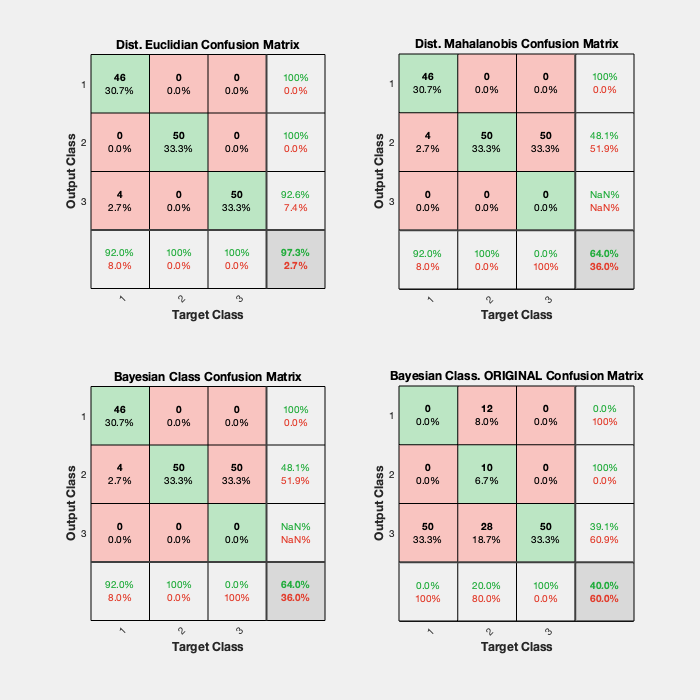

ind_t1=find(ytest==1);ind_t2=find(ytest==2); ind_t3=find(ytest==3);
Targets=zeros(c,Nt);
Targets(1,ind_t1)=1; Targets(2,ind_t2)=1; Targets(3,ind_t3)=1;

% Label Euclidian distance Classifier
ind_e1=find(z_euclidean==1); ind_e2=find(z_euclidean==2); ind_e3=find(z_euclidean==3);
OutputsE=zeros(c,Nt);
OutputsE(1,ind_e1)=1; OutputsE(2,ind_e2)=1; OutputsE(3,ind_e3)=1;

% Label Mahalanobis distance Classifier
ind_m1=find(z_mahalanobis==1); ind_m2=find(z_mahalanobis==2); ind_m3=find(z_mahalanobis==3);
OutputsM=zeros(c,Nt);
OutputsM(1,ind_m1)=1; OutputsM(2,ind_m2)=1; OutputsM(3,ind_m3)=1;

% Label Bayes Classifier with Estimates Parameters
ind_b1=find(z_bayesian==1); ind_b2=find(z_bayesian==2); ind_b3=find(z_bayesian==3);
OutputsB=zeros(c,Nt);
OutputsB(1,ind_b1)=1; OutputsB(2,ind_b2)=1; OutputsB(3,ind_b3)=1;

% Label Bayes Classifier With Original Parameters
ind_bo1=find(z_bayesian_Orig==1); ind_bo2=find(z_bayesian_Orig==2); ind_bo3=find(z_bayesian_Orig==3);
OutputsBO=zeros(c,Nt);
OutputsBO(1,ind_bo1)=1; OutputsBO(2,ind_bo2)=1; OutputsBO(3,ind_bo3)=1;

% Plot Confusion
figure;
plotconfusion(Targets,OutputsE,'Dist. Euclidian',Targets,OutputsM,'Dist. Mahalanobis',...
    Targets,OutputsB,'Bayesian Class',Targets,OutputsBO,'Bayesian Class. ORIGINAL' )